In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

red = [220 38 126] / 255;
blue = [100 143 255] / 255;
yellow = [255 176 0] / 255;
green = [45 182 125] / 255;

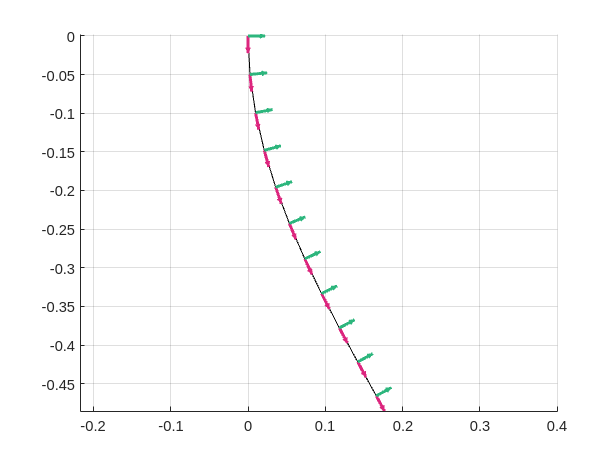

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists_target = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
q = calc_external_wrench(segment_twists_target, Q_tip, g_0);
a_target = -q;

## Valid design space

The purpose of the reaction contour is to efficiently sample the valid design space. Let us first naively sample the reaction space without it.

We have two options available:

- The most "accurate" way is to check for each arm design what the closest it can reach to the tip pose is. There is a question here of whether "closeness" is of tip position vs pose (do you consider angle?)

- A quicker way is to check the reaction residual

% WARNING: The following code takes 6 hours to run!!!
% DON'T FORGET TO SAVE YOUR DATA
run = true; 
if ~run
    error("Not running the code")
end

% Create a uniform sampling of the design space
rho_min = 0.02;
rho_max = 0.15;
l_0_min = 0.5;
l_0_max = 0.6;
N_designs_per_dim = 20;
%
rhos = linspace(rho_min, rho_max, N_designs_per_dim);
l_0s = linspace(l_0_min, l_0_max, N_designs_per_dim);
[R, L] = meshgrid(rhos, l_0s);
designs_rl = [R(:)'; L(:)'];
N_designs = size(designs_rl, 2);

% Preallocate storage space for loop times
times = zeros(1, N_designs);
p_solns = zeros(4, N_designs);
pose_residuals = zeros(1, N_designs);
reaction_residuals = zeros(1, N_designs);

% Initialize optimization initial values outside of the loop
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

tic
for i = 1 : N_designs
    t_start = tic;
    design_i = designs_rl(:, i);
    struct_design_i = make_antagonistic_struct_design(struct_design, design_i);

    opts = optimoptions("fmincon", Display="off");
    
    f_tip = @(p) cost_tip_pose_error(default_segment_twists, p, Q_tip, struct_design_i, poses(:, :, end));
    [p_solns(:, i), pose_residuals(i)] = fmincon(f_tip, [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50], [], opts); % TODO: Rename to soln_p
    reaction_residuals(i) = sum(vecnorm(check_equilibrium(segment_twists, Q_tip, p_solns(:, i), struct_design_i), 1));
    
    times(i) = toc(t_start);
    disp(i)
end

     1



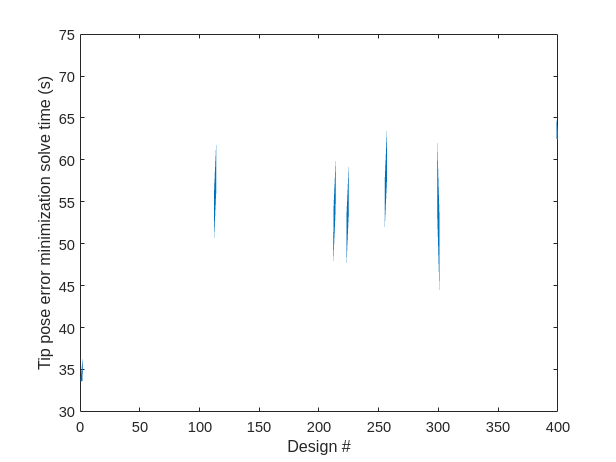

figure()
plot(times, "linewidth", 1.5);
xlabel("Design #")
ylabel("Tip pose error minimization solve time (s)")

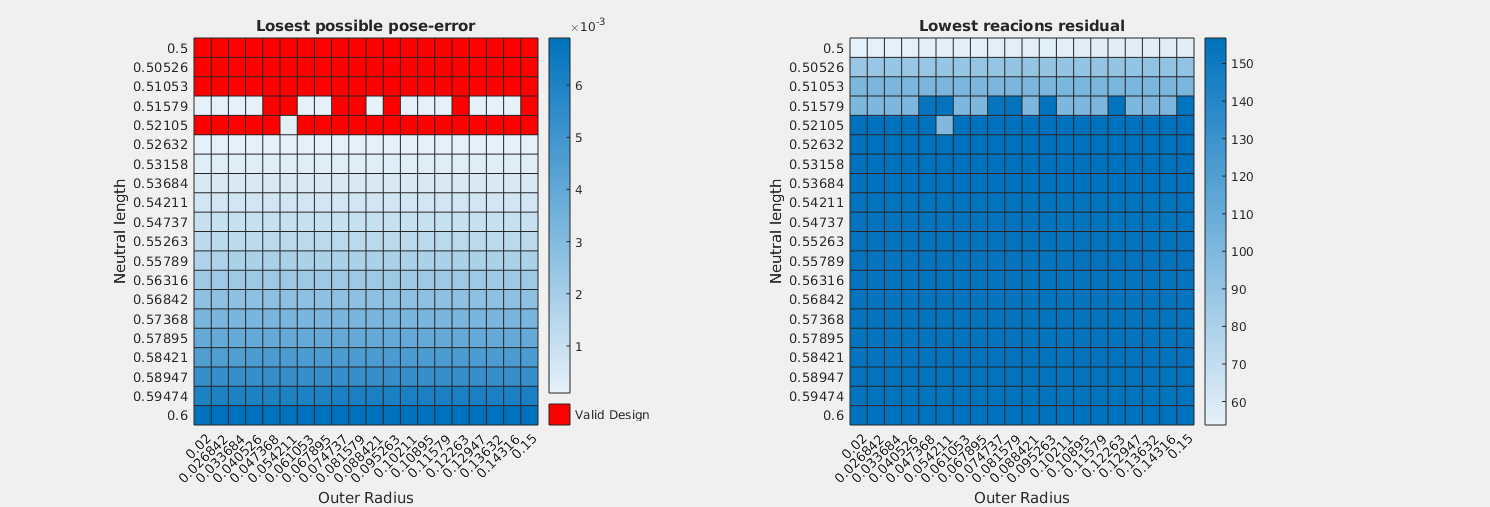

% Reshape the vectors back into meshgrid form
mat_pose_residuals = reshape(pose_residuals, size(R));
mat_reaction_residuals = reshape(reaction_residual, size(R));

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
hmap_data = round(mat_pose_residuals, 4);
hmap_data(hmap_data == 0) = nan;
hmap = heatmap(R(1, :), L(:, 1), hmap_data);
hmap.MissingDataColor = [1 0 0];
hmap.MissingDataLabel = 'Valid Design';
xlabel("Outer Radius")
ylabel("Neutral length")
title("Losest possible pose-error")

subplot(1, 2, 2);
heatmap(R(1, :), L(:, 1), mat_reaction_residuals);
xlabel("Outer Radius")
ylabel("Neutral length")
title("Lowest reacions residual")
set(gcf, "Visible", true);

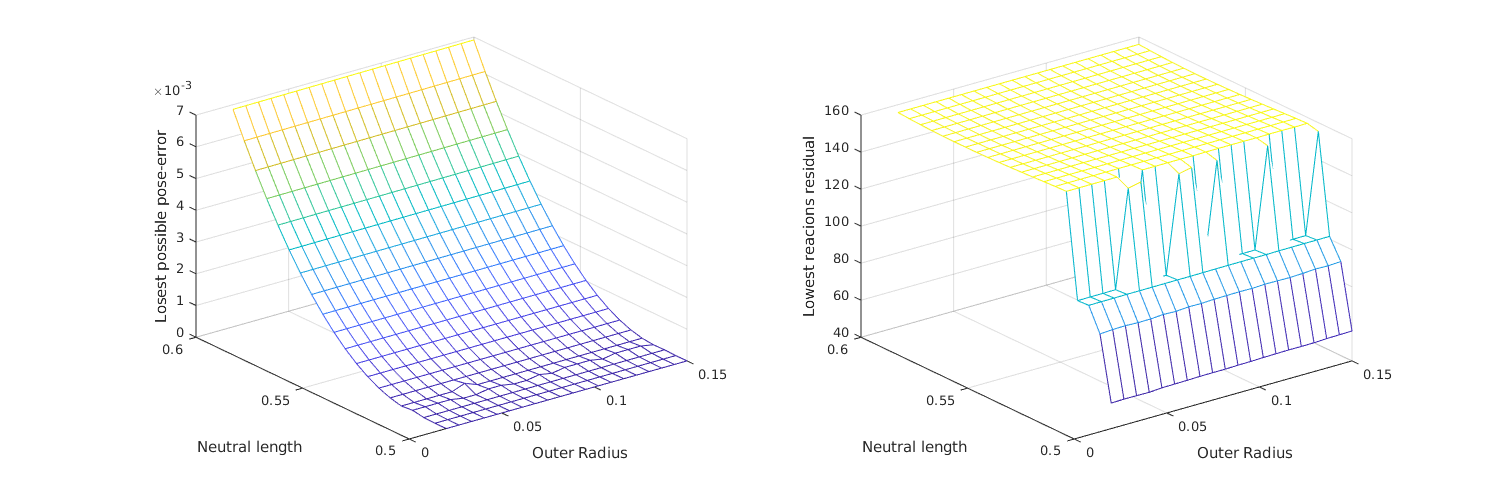

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
mesh(R, L, mat_pose_residuals);
xlabel("Outer Radius")
ylabel("Neutral length")
zlabel("Losest possible pose-error")

subplot(1, 2, 2);
mesh(R, L, mat_reaction_residuals);
xlabel("Outer Radius")
ylabel("Neutral length")
zlabel("Lowest reacions residual")
set(gcf, "Visible", true);

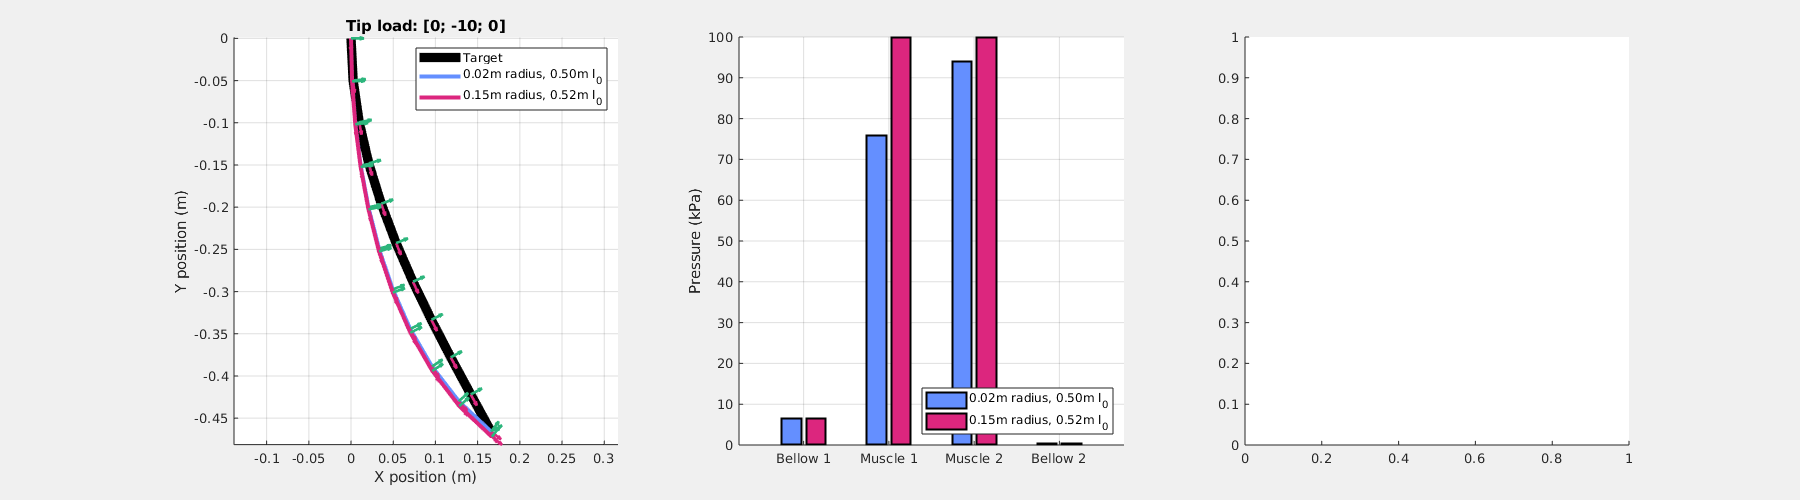

% Plot the equilibrium-shapes from two parts of the valid design space:
cell_mat_p_solns = reshape(num2cell(p_solns', 2), [N_designs_per_dim, N_designs_per_dim]);
cell_mat_designs = reshape(num2cell(designs_rl', 2), [N_designs_per_dim, N_designs_per_dim]);

% Pick out the two designs, which will be the first and last elements of
% the valid design space
i_valid_designs = find(mat_pose_residuals < 1e-4);

i_designs_to_plot = [i_valid_designs(1), i_valid_designs(end)];

segment_twists = zeros(3, N_poses, length(i_designs_to_plot));
names = strings(1, length(i_designs_to_plot));

% Iterate through the list of indices of designs that we want to visualize
for i = 1 : length(i_designs_to_plot)
    % Get the design parameters and pressure 
    i_design = i_designs_to_plot(i);
    design_i_rl = designs_rl(:, i_design);
    struct_design_i = make_antagonistic_struct_design(struct_design, design_i_rl);

    names(i) = sprintf("%.2fm radius, %.2fm l_0", design_i_rl(1), design_i_rl(2));

    p_soln_i = p_solns(:, i_design);
    
    % Solve the statics problem for this design with the pressures that
    % supposedly will get it to the target
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, p_soln_i, struct_design_i);
    [segment_twists(:, :, i), residual_i] = fsolve(f, default_segment_twists, opts);
end

%% Plot all of the results
figure("Position", [0, 0, 1800, 500], "Visible", true)
ax = subplot(1, 3, 1);
hold on
colors = [blue; red; yellow];

% Plot the target shape
plot_poses(calc_poses(g_0, segment_twists_target), ax, struct(color="k", linewidth=7), true, 0.1)
for i = 1 : length(i_designs_to_plot)
    % For each segment twist, compute the corresponding poses and plot them
    plot_poses(calc_poses(g_0, segment_twists(:, :, i)), ax, struct(color=colors(i, :), linewidth=3), true, 0.1);
end
legend(["Target", names])
grid on
xlabel("X position (m)")
ylabel("Y position (m)")
title("Tip load: [0; -10; 0]");
ax = subplot(1, 3, 2);
hold on;
bar_xlabels = ["Bellow 1", "Muscle 1", "Muscle 2", "Bellow 2"];
bar_handles = bar(bar_xlabels, p_solns(:, i_designs_to_plot), "Linewidth", 1.5);
for i = 1 : length(bar_handles)
    bar_handles(i).FaceColor = 'flat';
    bar_handles(i).CData = colors(i, :);
end
legend(names, "location", "southeast")
ylabel("Pressure (kPa)")
grid on

ax = subplot(1, 3, 3);

rounded_residuals = round(mat_pose_residuals, 4);
rounded_residuals(rounded_residuals == 0) = nan;

## Conclusion

**Summary:** In this document we first explored the reaction space for a variable curvature rod. have shown a naive method of surveying the continuum arm design space for antagonistic segment geometries (neutral lengths and outer actuator radii) for which there exists a control input that will drive them to reach the target loaded tip pose. 

function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function ps = outline_pressure_space(max_ps, actuation_mode, N_edge)
    %%% Create a square path in pressure-space with N_edge points along each
    %%% edge using a corner definition: min_ps defines the bottom left
    %%% corner, and max_ps defines the top right corner. The path begins
    %%% and ends at the bottom left corner.
    %%%
    %%% Parameters:
    %%%  - max_ps: [60, 100, 100, 60] (kpa)
    %%%  - actuation_mode: [1 2 1 2]
    %%%  - N_edge: 50

    % Determine the phases of each trapezoid wave based on the actuation
    % modes. 
    % Currently mode-2 is defined starting a quarter period later than mode1
    phases = zeros(size(actuation_mode));
    for i = 1 : length(actuation_mode)
        mode_i = actuation_mode(i);
        
        if mode_i == 1
            phases(i) = 0;
        elseif mode_i == 2
            phases(i) = 1;
        end
    end
    
    t = linspace(0, 4, N_edge*4);
    ps = zeros(length(max_ps), length(t));
    for i = 1 : length(max_ps)
        ps(i, :) = max_ps(i) * trapezoid_wave(t - phases(i));
    end
end

function sig = trapezoid_wave(s)
    %%% Sample a trapzoid wave with period 1s at times s.
    %%% The trapezoid has amplitude 0.5 and is centered at 0.5
    %%% ie, it switches between 0 and 1.
    s = mod(s, 4);
    sig = zeros(size(s));
    for i = 1 : length(s)
        s_i = s(i);
        
        if s_i < 1
            sig(i) = 1 * (s_i);
        elseif (s_i >= 1) && (s_i < 2)
            sig(i) = 1;
        elseif (s_i >= 2) && (s_i < 3)
            sig(i) = -1 * (s_i - 2) + 1;
        else
            sig(i) = 0;
        end
    end
end

function cost = cost_first_reaction_diff(twists, pressure, struct_design, a_target)
    rxns = calc_reaction_wrench(twists, pressure, struct_design);
    cost = norm(rxns(:, 1) - a_target(:, 1));
end

function cost = cost_tip_pose_error(twists_0, pressure, Q_tip, struct_design, g_target)
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, pressure, struct_design);
    
    soln = fsolve(f, twists_0, opts);
    
    poses = calc_poses(struct_design.g_0, soln);
    delta_g_extrinsic = Pose2.vee(poses(:, :, end)) - Pose2.vee(g_target);
    K = diag([1 1 0]);
    cost = delta_g_extrinsic' * K * delta_g_extrinsic;
    %delta_g = inv(poses(:, :, end)) * g_target;
    %cost = norm(Twist2.vee(logm(delta_g)));
end

function struct_design_out = make_antagonistic_struct_design(struct_design_base, design_rl)
    struct_design_out = struct_design_base;
    struct_design_out.rhos  = [design_rl(1), 0.02, 0.02, design_rl(1)]; % Here we just sweep the outer radius
    struct_design_out.l_0 = design_rl(2);
end